# optimize event mining 

1.remove duplicate 

Events with same K and starting time were removed expect the one with highest M. 

load('em_arena_th0.5.mat')
close all
p=6;m=1;
max(em{1,1}.ne{p,m})

ans = 1924

subplot(2,1,1)
plot(em{1,1}.ne{p,m});hold on 
plot(find(em{2,1}.timefilter{p,m}),em{2,1}.ne{p,m});
em=rem_dup_em(em);
max(em{1,1}.ne{p,m})

ans = 1824

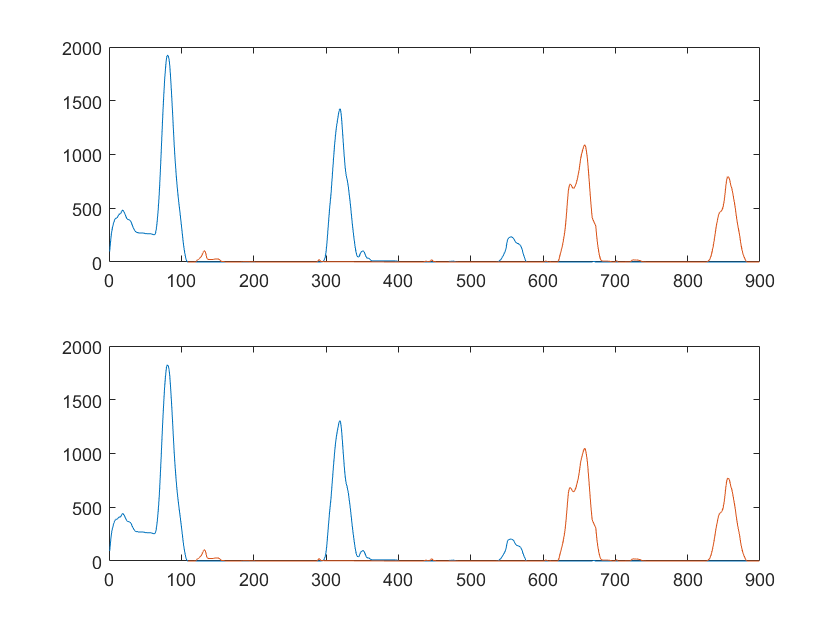

subplot(2,1,2)
plot(em{1,1}.ne{p,m});hold on
plot(find(em{2,1}.timefilter{p,m}),em{2,1}.ne{p,m});

Same starting time and K with lower M is not the major source of duplication...? 